Calculates EOD frequency statistics for the Brasil *Eigenmannia* data.

% Data are found in these files - load them before running this script
% load CaveDataRev2018a.mat
% load SurfaceDataRev2018a.mat

## Setup


% Set the number of bins for the histogram here:

    numbins = 20;

    

## Extract the EOD frequency values for each fish


CaveFreqs = []; 
SurfaceFreqs = []; 
CaveVars = []; 
SurfaceVars = []; 

% Cycle through every fish in the Surface data
for j=1:length(srf) 
    for k=1:length(srf(j).fish) 
        SurfaceFreqs(end+1) = nanmean(srf(j).fish(k).freq(:,2)); 
        SurfaceVars(end+1) = nanstd(srf(j).fish(k).freq(:,2));
    end
end

% Cycle through every fish in the Cave data
for j=1:length(cave)
    for k=1:length(cave(j).fish)
        CaveFreqs(end+1) = nanmean(cave(j).fish(k).freq(:,2)); 
        CaveVars(end+1) = nanstd(cave(j).fish(k).freq(:,2));
    end
end


## Calculate the EOD frequency statistics for surface and cavefish EOD Frequencies

    meanSurfaceFreq = nanmean(SurfaceFreqs);
    meanCaveFreq = nanmean(CaveFreqs);
    medianSurfaceFreq = nanmedian(SurfaceFreqs);
    medianCaveFreq = nanmedian(CaveFreqs);
    
fprintf('SURFACE: MinEODfreq = %3.2f, MaxEODfreq = %3.2f, N = %i \n', min(SurfaceFreqs), max(SurfaceFreqs), length(SurfaceFreqs));    

SURFACE: MinEODfreq = 299.93, MaxEODfreq = 435.60, N = 110 


fprintf('CAVE: MinEODfreq = %3.2f, MaxEODfreq = %3.2f, N = %i \n', min(CaveFreqs), max(CaveFreqs), length(CaveFreqs));    

CAVE: MinEODfreq = 230.05, MaxEODfreq = 478.57, N = 82 


fprintf('SURFACE MeanEODfreq = %3.2f, MedianEODfreq = %3.2f \n', meanSurfaceFreq, medianSurfaceFreq);

SURFACE MeanEODfreq = 375.77, MedianEODfreq = 382.02 


fprintf('CAVE MeanEODfreq = %3.2f, MedianEODfreq = %3.2f \n', meanCaveFreq, medianCaveFreq);

CAVE MeanEODfreq = 356.62, MedianEODfreq = 360.84 



[P,H,STATS] = ranksum(CaveFreqs, SurfaceFreqs);    
    fprintf('Wilcoxon RankSum: Surface vs Cave EOD freqs? pVal = %1.4f, Z = %1.4f \n', P, STATS.zval);

Wilcoxon RankSum: Surface vs Cave EOD freqs? pVal = 0.0100, Z = -2.5743 


    
% [stts.f.H, stts.f.P, stts.f.CI, stts.f.STATS] = ttest2(CaveFreqs, SurfaceFreqs, 'vartype', 'unequal');
% 
%     fprintf('TTEST2 Cave vs Surface EOD freqs? pVal = %1.5f, CI = %1.5f %1.5f \n', stts.f.P, stts.f.CI(1), stts.f.CI(2));
%     stts.f.STATS
%     fprintf('Cave mean & std Hz %1.4f %1.4f \n', stts.meanCaveFreq, stts.stdCaveFreq);
%     fprintf('Surface mean & std Hz %1.4f %1.4f \n', stts.meanSurfaceFreq, stts.stdSurfaceFreq); 



## Plot the frequency data for the manuscript

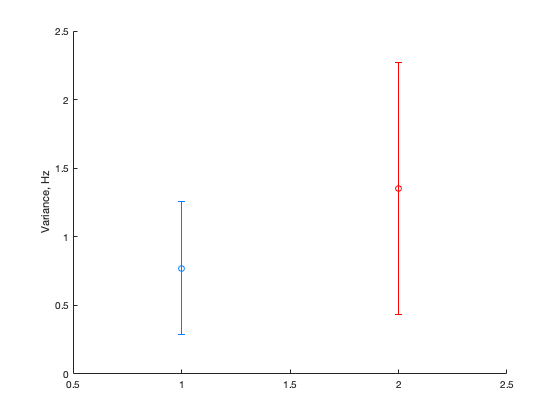

% Get the ranges for the plot
minfreq = min([SurfaceFreqs CaveFreqs]);
maxfreq = max([SurfaceFreqs CaveFreqs]);
    ctrs = minfreq:(maxfreq - minfreq)/numbins:maxfreq;
        
% figure(1); clf; hold on; % NOT USED IN MANUSCRIPT
%     histogram(SurfaceFreqs, ctrs, 'FaceColor', '[0 0.5 1]');
%     histogram(CaveFreqs, ctrs, 'FaceColor', '[1 0 0]'); 

% figure(2); clf; hold on; % NOT USED IN MANUSCRIPT
%     surfhist = histcounts(SurfaceFreqs, ctrs);
%         surfhist = surfhist / sum(surfhist);
%     cavehist = histcounts(CaveFreqs, ctrs);
%         cavehist = cavehist / sum(cavehist);
        
    plotspots = ctrs(2:end) - (maxfreq - minfreq)/(2*numbins);
    plot(plotspots, surfhist, 'Color', '[0 0.5 1]', "LineWidth", 2);
    plot(plotspots, cavehist, 'Color', '[1 0 0]', "LineWidth", 2);

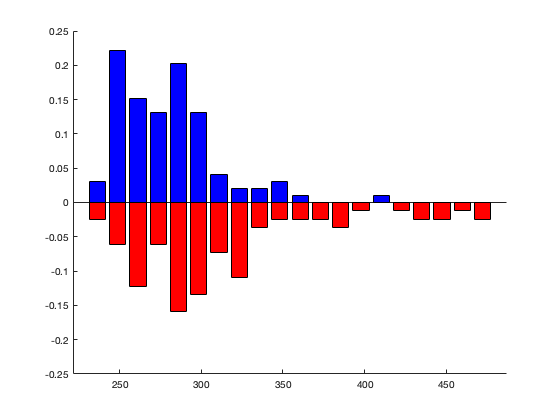

    
figure(3); clf; hold on;
    bar(plotspots, surfhist, 'b');
    bar(plotspots, -cavehist, 'r');
    ylim([-0.25, 0.25])

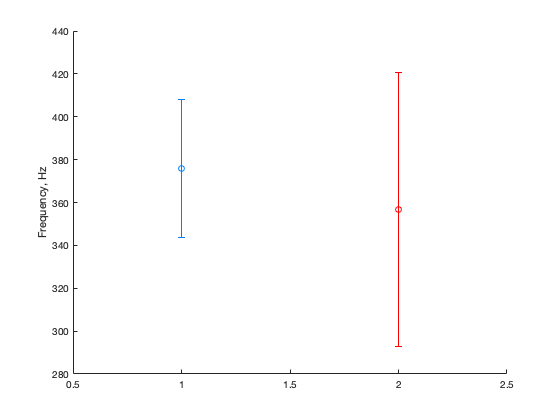

    
figure(4); clf; hold on; % NOT USED IN MANUSCRIPT
    plot(1, stts.meanSurfaceFreq, 'o', 'Color', '[0 0.5 1]');
        errorbar(1, stts.meanSurfaceFreq, stts.stdSurfaceFreq, 'Color', '[0 0.5 1]')
    plot(2,stts.meanCaveFreq, 'o', 'Color', '[1 0 0]')
        errorbar(2, stts.meanCaveFreq, stts.stdCaveFreq, 'Color', '[1 0 0]')
    xlim([0.5 2.5])
    ylabel('Frequency, Hz');

## Calculate the EOD frequency variability statistics for surface and cavefish

    TubeIDXs = [7, 9, 11, 23, 30, 31, 55, 61, 75, 80, 84];
    otherIDXs = setdiff([1:length(SurfaceVars)], TubeIDXs);

    stts.meanSurfaceVar = nanmean(SurfaceVars(otherIDXs));
    stts.meanCaveVar = nanmean(CaveVars);
    stts.stdSurfaceVar = nanstd(SurfaceVars(otherIDXs));
    stts.stdCaveVar = nanstd(CaveVars);    

    stts.meanTubeVar = nanmean(SurfaceVars(TubeIDXs));
    stts.meanTubeVar = nanvar(SurfaceVars(TubeIDXs));
        
[stts.v.H, stts.v.P, stts.v.CI, stts.v.STATS] = ttest2(CaveVars, SurfaceVars(otherIDXs), 'vartype', 'unequal');
    
    fprintf('ttest2 cave and surface VARs? pVal = %1.5f, CI = %1.5f %1.5f \n', stts.v.P, stts.v.CI(1), stts.v.CI(2));

ttest2 cave and surface VARs? pVal = 0.00000, CI = 0.35872 0.80377 


    stts.v.STATS

ans = struct with fields:
    tstat: 5.1726
       df: 117.7829
       sd: [0.9166 0.4856]


    fprintf('Cave mean & std STD %1.4f %1.4f \n', stts.meanCaveVar, stts.stdCaveVar);

Cave mean & std STD 1.3511 0.9166 


    fprintf('Surface mean & std SRD %1.4f %1.4f \n \n', stts.meanSurfaceVar, stts.stdSurfaceVar); 

Surface mean & std SRD 0.7699 0.4856 
 


    
[stts.Tube.H, stts.Tube.P, stts.Tube.CI, stts.Tube.STATS] = ttest2(SurfaceVars(otherIDXs), SurfaceVars(TubeIDXs), 'vartype', 'unequal');
fprintf('Surface Var mean & Tube Var mean %1.4f %1.4f \n', stts.meanSurfaceVar, stts.meanTubeVar);

Surface Var mean & Tube Var mean 0.7699 0.0707 


    stts.Tube.P

ans = 0.0100

    stts.Tube.STATS

ans = struct with fields:
    tstat: 2.8671
       df: 18.5198
       sd: [0.4856 0.2660]


## Plot the Variance data (in four different ways!)

minvar = min([SurfaceVars(otherIDXs), CaveVars]);
maxvar = max([SurfaceVars(otherIDXs), CaveVars])

maxvar = 3.9378

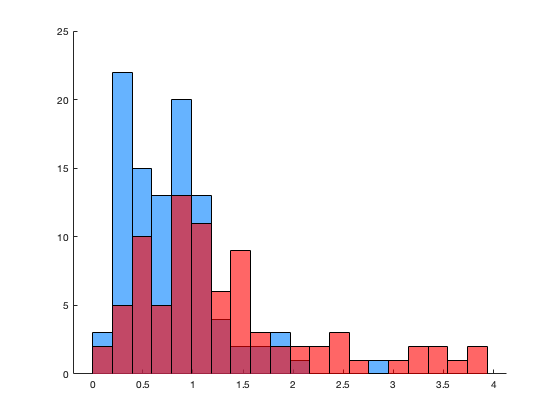

    ctrs = minvar:(maxvar - minvar)/numbins:maxvar;
    
    
figure(5); clf; hold on;
    histogram(SurfaceVars(otherIDXs), ctrs, 'FaceColor', '[0 0.5 1]');
    histogram(CaveVars, ctrs, 'FaceColor', '[1 0 0]'); 

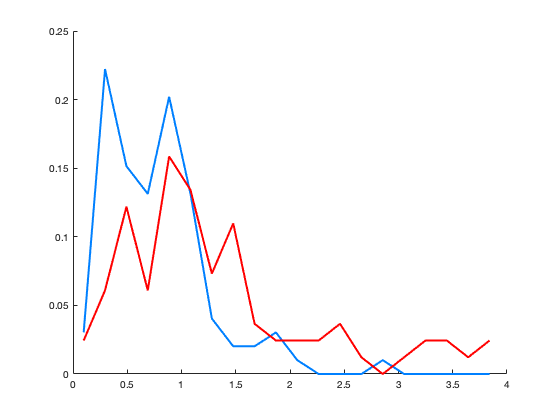


figure(6); clf; hold on;
    surfhist = histcounts(SurfaceVars(otherIDXs), ctrs);
        surfhist = surfhist / sum(surfhist);
    cavehist = histcounts(CaveVars, ctrs);
        cavehist = cavehist / sum(cavehist);
        
    plotspots = ctrs(2:end) - (maxvar - minvar)/(2*numbins);
    plot(plotspots, surfhist, 'Color', '[0 0.5 1]', "LineWidth", 2);
    plot(plotspots, cavehist, 'Color', '[1 0 0]', "LineWidth", 2);

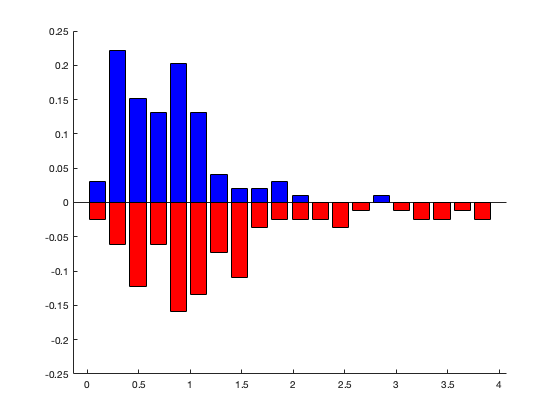

    
figure(7); clf; hold on;
    bar(plotspots, surfhist, 'b');
    bar(plotspots, -cavehist, 'r');
    ylim([-0.25, 0.25])

    
figure(8); clf; hold on;
    plot(1, stts.meanSurfaceVar, 'o', 'Color', '[0 0.5 1]');
        errorbar(1, stts.meanSurfaceVar, stts.stdSurfaceVar, 'Color', '[0 0.5 1]')
    plot(2,stts.meanCaveVar, 'o', 'Color', '[1 0 0]')
        errorbar(2, stts.meanCaveVar, stts.stdCaveVar, 'Color', '[1 0 0]')
    xlim([0.5 2.5])
    ylabel('Variance, Hz');

## Are EOD Frequency and Variability linked?

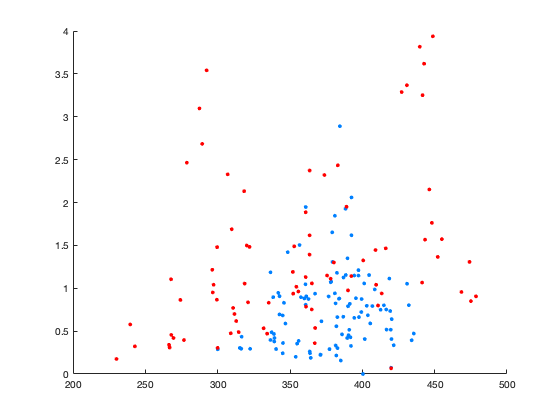


    figure(9); clf; hold on;
    
    plot(SurfaceFreqs, SurfaceVars, '.', 'Color', '[0, 0.5, 1]', 'MarkerSize', 8)
    plot(CaveFreqs, CaveVars, '.', 'Color', '[1, 0 , 0]', 'MarkerSize', 8)